# Lab1

## Part1

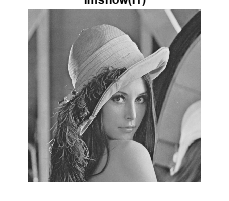

close all
I1=imread("lena_gray.bmp"); %file type uint8. image size 512*512
%3
figure();
imtool(I1);
%4
figure();
imshow(I1);title("imshow(I1)");

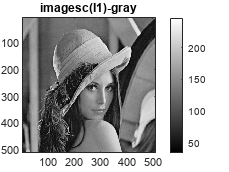

%5
fi=figure();
imagesc(I1);title("imagesc(I1)-gray");
colormap("gray");
colorbar;
imwrite(I1,'lena_gray_gray.jpg');
saveas(fi,'lena_gray_gray_with_bar.jpg');

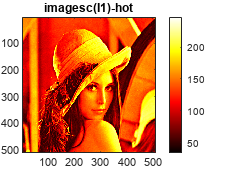

%6
fi=figure();
imagesc(I1);title("imagesc(I1)-hot");
colormap(hot);
colorbar;
imwrite(I1,colormap("hot"),'lena_gray_hot.jpg');
saveas(fi,'lena_gray_hot_with_bar.jpg');

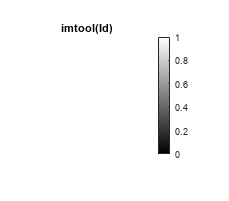


%7
Id=double(I1); 
%8.4
fi=figure();
imshow(Id); title("imtool(Id)");
colorbar;
saveas(fi,'lena_gray_double.jpg');

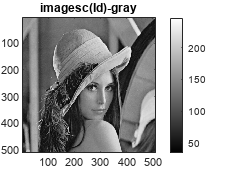

%8.5
fi=figure();
imagesc(Id); title("imagesc(Id)-gray");
colormap("gray");
colorbar;
saveas(fi,'lena_gray_gray2.jpg');

## Part2

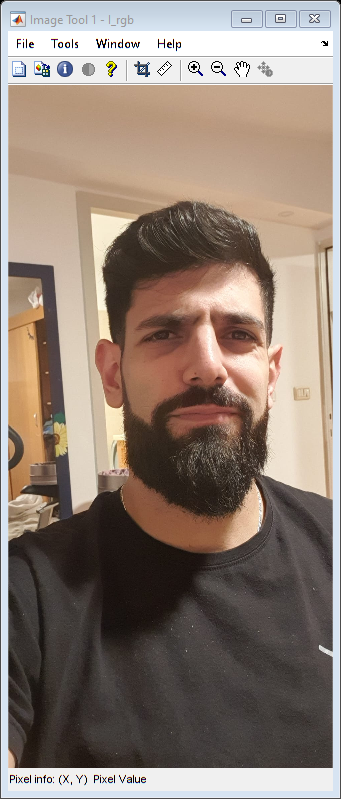

close all
%a
I_rgb=imread("ben.jpg");
s=size(I_rgb);
%b
figure();
imtool(I_rgb);

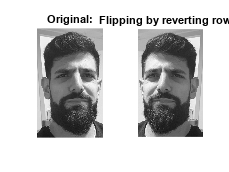

%d
rect= [224 316 607 1006];
I2= imcrop(I_rgb,rect);
%e
imresize(I2,2,"bilinear");
%f
I=rgb2gray(I2);
imwrite(I,"head.jpg");
%g
maxHead=max(I(:));
minHead=min(I(:));

%h
fi=figure();
[r,c]=size(I);
for row_H_first=1:1:r
    k=1;
    for j=c:-1:1
        temp=I(row_H_first,k);
        result(row_H_first,k)=I(row_H_first,j);
        result(row_H_first,j)=temp;
        k=k+1;
    end
end
subplot(1,2,1),imshow(I);
title('Original:');
subplot(1,2,2),imshow(result);
title('Flipping by reverting rows:');
saveas(fi,'head_original_FlipRows.jpg');

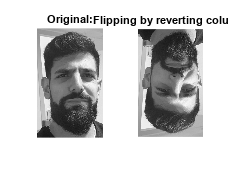

%i
fi=figure();
[r,c]=size(I);
for col_H_first=1:1:c
    k=1;
    for j=r:-1:1
        temp=I(k,col_H_first);
        result2(k,col_H_first)=I(j,col_H_first);
        result2(j,col_H_first)=temp;
        k=k+1;
    end
end
subplot(1,2,1),imshow(I);
title('Original:');
subplot(1,2,2),imshow(result2);
title('Flipping by reverting colums:');
saveas(fi,'head_original_FlipCols.jpg');

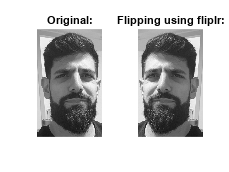


%j1 fliplr
fi=figure();
resj1=fliplr(I);
subplot(1,2,1),imshow(I);
title('Original:');
subplot(1,2,2),imshow(resj1);
title('Flipping using fliplr:');
saveas(fi,'head_original_fliplr.jpg');

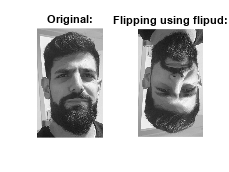


%j2 flipud
fi=figure();
resj2=flipud(I);
subplot(1,2,1),imshow(I);
title('Original:');
subplot(1,2,2),imshow(resj2);
title('Flipping using flipud:');
saveas(fi,'head_original_flipud.jpg');

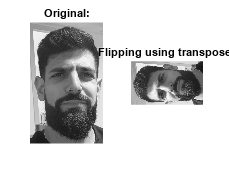


%j3 flip with transpose
fi=figure();
resj3=I';
subplot(1,2,1),imshow(I);
title('Original:');
subplot(1,2,2),imshow(resj3);
title('Flipping using transpose:');
saveas(fi,'head_original_transpose.jpg');

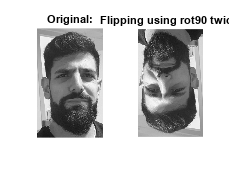


%k
fi=figure();
rotatedI=rot90(rot90(I));
subplot(1,2,1),imshow(I);
title('Original:');
subplot(1,2,2),imshow(rotatedI);
title('Flipping using rot90 twice:');
saveas(fi,'head_original_rotated.jpg');

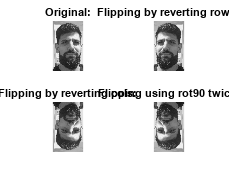


%l
fi=figure();
subplot(2,2,1); imshow(I);
title('Original:');
subplot(2,2,2);imshow(result);
title('Flipping by reverting rows:');
subplot(2,2,3); imshow(result2);
title('Flipping by reverting cols:');
subplot(2,2,4); imshow(rotatedI);
title('Flipping using rot90 twice:');
saveas(fi,'head_all_4.jpg');

## Part3

%1
close all;
h=fspecial('disk',20);
%a
whos h;

  Name       Size            Bytes  Class     Attributes

  h         41x41            13448  double              



%b
hmin = min(h(:));
hmax=max(h(:));
%c ?
h1=h./hmax;
whos h1;

  Name       Size            Bytes  Class     Attributes

  h1        41x41            13448  double              



%d
h1_padded = padarray(h1,[40 10],"both");
whos h1_padded;

  Name             Size            Bytes  Class     Attributes

  h1_padded      121x61            59048  double              



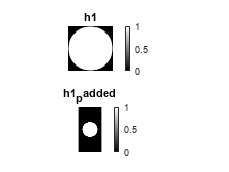

%e
fi=figure();
subplot(2,1,1);
imshow(h1);
title("h1");
colorbar;
subplot(2,1,2);
imshow(h1_padded);
title("h1_padded");
colorbar;
saveas(fi,'h1_h1padded.jpg')

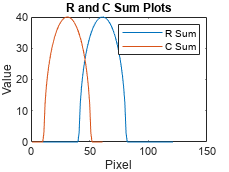

%f
row_H_first=1;
while(h1_padded(row_H_first,:)==0)
    row_H_first=row_H_first+1;
end
row_H_last=121;
while(h1_padded(row_H_last,:)==0)
    row_H_last=row_H_last-1;
end
%g
col_H_first=1;
while(h1_padded(:,col_H_first)==0)
    col_H_first=col_H_first+1;
end
col_H_last=61;
while(h1_padded(:,col_H_last)==0)
    col_H_last=col_H_last-1;
end
%h
fi=figure();
C_sum = sum(h1_padded,1);
R_sum = sum(h1_padded,2);
plot(R_sum);
hold on;
plot(C_sum);
legend('R Sum', 'C Sum');
xlabel('Pixel');
ylabel('Value');
title('R and C Sum Plots');
saveas(fi,"C_sum_R_sum.jpg");

## Part4

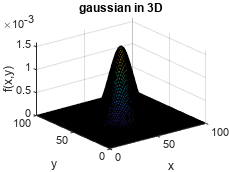

close all
%2
fi=figure();
h=fspecial('gaussian',[100,100],10);
%3 varible type is double. 
typeCheck=isinteger(h);
Size=size(h);%size is 100x100.
%a
minNum=min(h(:));%min is 3.6351e-14
maxNum=max(h(:));%max is 0.0016
%b
surf(h);
xlabel('x');
ylabel('y');
zlabel('f(x,y)');
title('gaussian in 3D')%%%needs title and axes names
saveas(fi,'guassian3D.jpg');

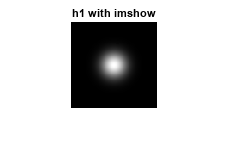

%c
h1=h./maxNum;
%d
fi=figure();
imshow(h1);
title('h1 with imshow');
saveas(fi,'h1Normal.jpg');

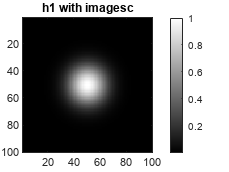

%e
fi=figure();
imagesc(h1),colormap(gray),colorbar;
title('h1 with imagesc');
saveas(fi,'h1Normal_imagesc.jpg');

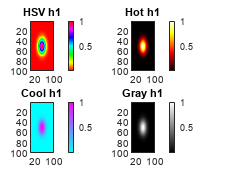


%f
fi=figure();
subplot(2,2,1), imagesc(h1), colormap(subplot(2,2,1),"hsv"),colorbar, title('HSV h1');
subplot(2,2,2), imagesc(h1), colormap(subplot(2,2,2),'hot'),colorbar, title('Hot h1');
subplot(2,2,3), imagesc(h1), colormap(subplot(2,2,3),'cool'),colorbar, title('Cool h1');
subplot(2,2,4), imagesc(h1), colormap(subplot(2,2,4),'gray'),colorbar, title('Gray h1');
saveas(fi,'h1_4colors.jpg');